# **ACM/IDS 104 - Problem Set 6 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

***NOTE:*** Start with Problem 1, at the *bottom of this livescript*. (It's at the bottom because it's a MATLAB live function)

## Problem 2 (10 points) Ranking US Airports using PageRank

The PageRank algorithm can be used for ranking not only web pages, but any "entities'' organized into a network. The $\texttt{USAirTransportation.mat}$ file contains the adjacency matrix $A$ for the network of (anonymized) US airports: nodes represent airports and links represent air travel connections among them. That is, airports $i$ and $j$ are connected $\left(A_{ij}=1\right)$ if there are direct flights between them. The network in $\texttt{USAirTransportation.mat}$ is obtained by considering the 500 US airports with the largest amount of traffic from [publicly available data](https://toreopsahl.com/datasets/#usairports). Implement the PageRank algorithm (see Lecture 12) for ranking the airports. Use your function from Problem 1 for finding the importance score vector. What are the ID numbers of 10 most important airports for $\alpha = 0.10, 0.15, 0.20$? 

Functions that may be useful for this problem:


$$\texttt{repmat(), sort(), disp(), strcat(), num2str()}$$


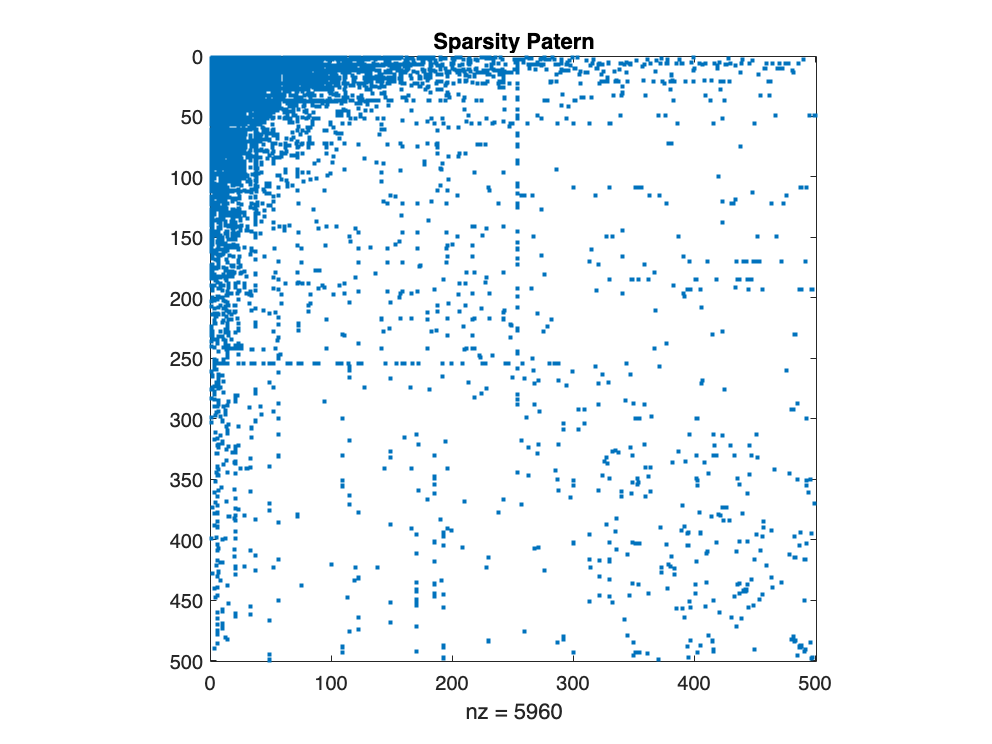

load USAirTransportation.mat % dataset
%{
Let us see how matrix A looks like
%}
figure;
spy(A);
title('Sparsity Patern');

alpha = [0.10 0.15 0.20]; % values of alpha
[~,n]=size(A); % size of A
%{
Implement the algorithm below
You can use bar() to visualize the scores
Report the top 10 airports (in descending order) for each alpha
%}

% Recall Page Rank only works on stochastic matrices. This will be A_prime
A_prime = zeros(n, n);
for i = 1:n
    column_i = A(:, i);
    A_prime(:, i)= column_i/sum(column_i);
end

S = zeros(n, n);
S(:) = 1/n;
alpha_n = alpha';

for j = 1:size(alpha_n)
    Apb = (1 - alpha_n(j))*A_prime*alpha_n(j)*S;
    [lambda, v] = power_method(Apb);
    v_top = sort(v, 'descend');
    maxVals = v_top(1:10, 1);
    indices = zeros(0,1);
    for k = 1:10
        idx_int = find(v == maxVals(k, 1));
        indices = [indices; idx_int];
    end
    fprintf('Top 10 matrices in descending order for alpha = %.2f,\n', alpha_n(j));
    for p = 1:size(indices)
        disp(indices(p));
    end
    fprintf('\n');
end

Top 10 matrices in descending order for alpha = 0.10,


     6

     3

     1

    21

     7

    10

    11

    12

     2

    14



Top 10 matrices in descending order for alpha = 0.15,


     6

     3

     1

    21

     7

    10

    11

    12

     2

    14



Top 10 matrices in descending order for alpha = 0.20,


     6

     3

     1

    21

     7

    10

    11

    12

     2

    14



## Problem 5 (10 points) Principal Component Analysis

In this problem, you will find the principal components of the dataset $\texttt{pca\_data.mat}$, which contains the $m\times n$ matrix $X$. Columns of $X$ correspond to $n=10^4$ measurements and rows of $X$ correspond to $m=2$ quantities (features). Let us see what the data looks like:

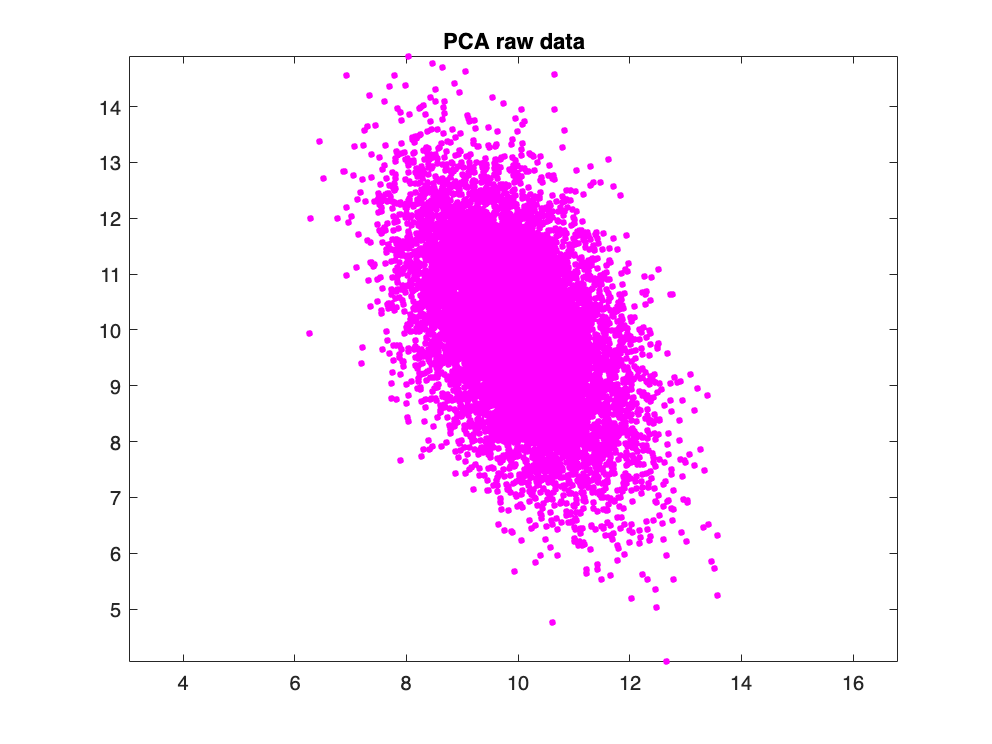

load pca_data.mat
figure;
plot(X(1,:),X(2,:),'.m','MarkerSize',10);
title("PCA raw data");
axis equal

### Part (a)

Find the $m\times m$ covariance matrix of $X$. Use $\texttt{disp()}$ to display it.

[m, n] = size(X);
X0 = zeros(m, n);
ct = mean(X, 2);
X0(1, :) = X(1, :) - ct(1);
X0(2, :) = X(2, :) - ct(2);
covariance = (1/n) * (X0) * (X0');
disp('Covariance matrix of X: ');

Covariance matrix of X: 


disp(covariance);

    0.9829   -0.6808
   -0.6808    1.9508



### Part (b)

Find the $m$ principal components of $X$ and show them on top of the original data. That is, if $v$ is a principal component, then plot the line $l(t) = \mu+vt$ over the scatter plot shown above, where $\mu\in\mathbb{R}^2$ is the centroid of the data.

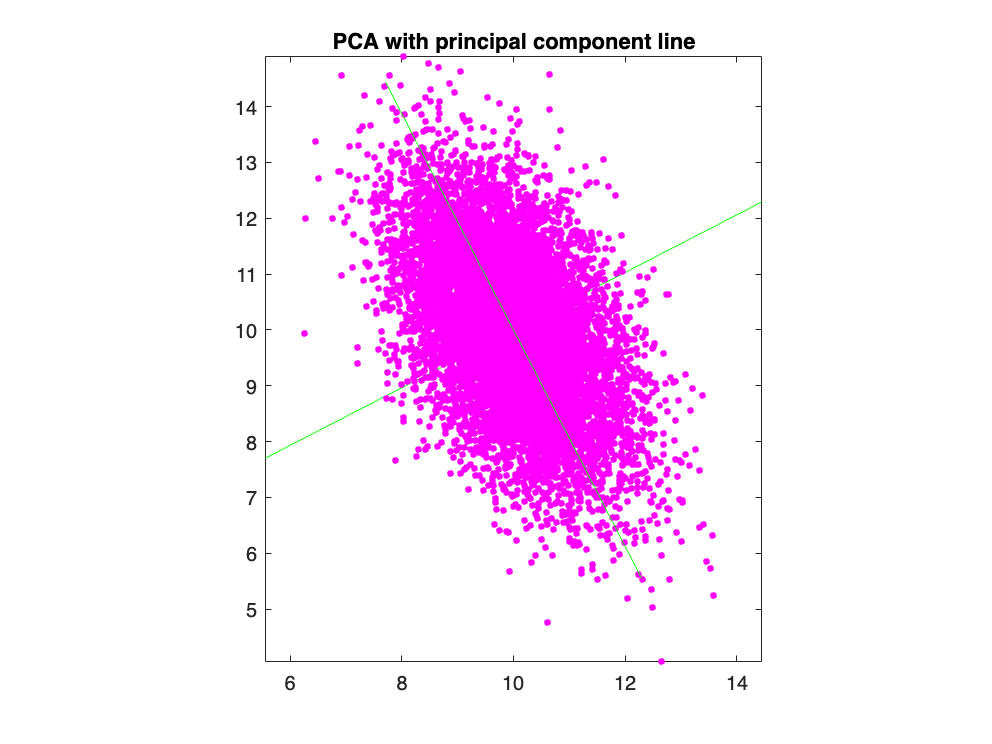

%{
Find the eigenvectors
Normalize
Obtain the centroids
Create the lines
Plot
%}
[v, useless] = eig(covariance); %not using power_method in case it's off. 
syms t
figure;
x = ct(1) + t * v(1, 1);
y = ct(2) + t * v(2, 1);
fplot(x, y, '-g');
hold on
x = ct(1) + t * v(1, 2);
y = ct(2) + t * v(2, 2);
plot(X(1,:),X(2,:),'.m','MarkerSize',10);
title("PCA with principal component line");
axis equal
fplot(x, y, '-g');
hold off

### Part (c)

If we change the basis of $\mathbb{R}^m$ from the standard basis to the basis of the principal components $[v_1,\cdots,v_m] = V$ of $X$, the data matrix will transform to $Y = V^{-1}X$. Find the covariance of the transformed data $Y$. Use $\texttt{disp()}$ to display it.

%fetching Y
Y = inv(v) * X;
Y0 = zeros(m ,n);
ct2 = mean(Y, 2);
Y0(1,:) = Y(1, :) - ct2(1);
Y0(2, :) = Y(2, :) - ct2(2);
Covy = (1/n) * (Y0) * (Y0');
disp('Covariance matrix of Y:');

Covariance matrix of Y:


disp(Covy)

    0.6316   -0.0000
   -0.0000    2.3021



### Part (d)

Principal component analysis is a very popular data analysis technique and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, this is a built-in function $\texttt{pca()}$. In the simplest form, $\texttt{V = pca(X)}$ returns the principal components of the data matrix $X$, where rows of $X$ correspond to the *measurements* and columns correspond to the *features*. Find the principal components of $X$ using $\texttt{pca()}$ and compare them with the ones found in part (b). Are they the same?

builtinPCA = pca(X');
disp('Built-in MATLAB PCA Results: ');

Built-in MATLAB PCA Results: 


disp(builtinPCA);

   -0.4586    0.8886
    0.8886    0.4586



disp('PCA results from part (B): ');

PCA results from part (B): 


disp(v)

   -0.8886   -0.4586
   -0.4586    0.8886



syms t
figure;
x = ct(1) + t * v(1, 1);
y = ct(2) + t * v(2, 1);
fplot(x, y, '-g');
hold on
x = ct(1) + t * v(1, 2);
y = ct(2) + t * v(2, 2);
plot(X(1,:),X(2,:),'.m','MarkerSize',10);
title("PCA with principal component line");
axis equal
fplot(x, y, '-g');
x = ct(1) + t * builtinPCA(1, 1);
y = ct(2) + t * builtinPCA(2, 1);
fplot(x, y, '-g');
x = ct(1) + t * v(1, 2);
y = ct(2) + t * v(2, 2);
fplot(x, y, '-g');
hold off

%as we can see, there are only 2 lines still, which means our results
%perfectly align with the built in PCA! :)

## Problem 6 (10 points) Spectral Method for Graph Partitioning

A complete graph $K_n$ with $n$ vertices is a graph in which each pair of graph vertices is connected by an edge. Let $G$ be a barbell-like graph obtained by connecting $K_{n_1}$ and $K_{n_2}$ with $m=3$ bridges, where $n_1=20$ and $n_2=30$. The graph $G$ and the sparsity pattern of its adjacency matrix are shown:

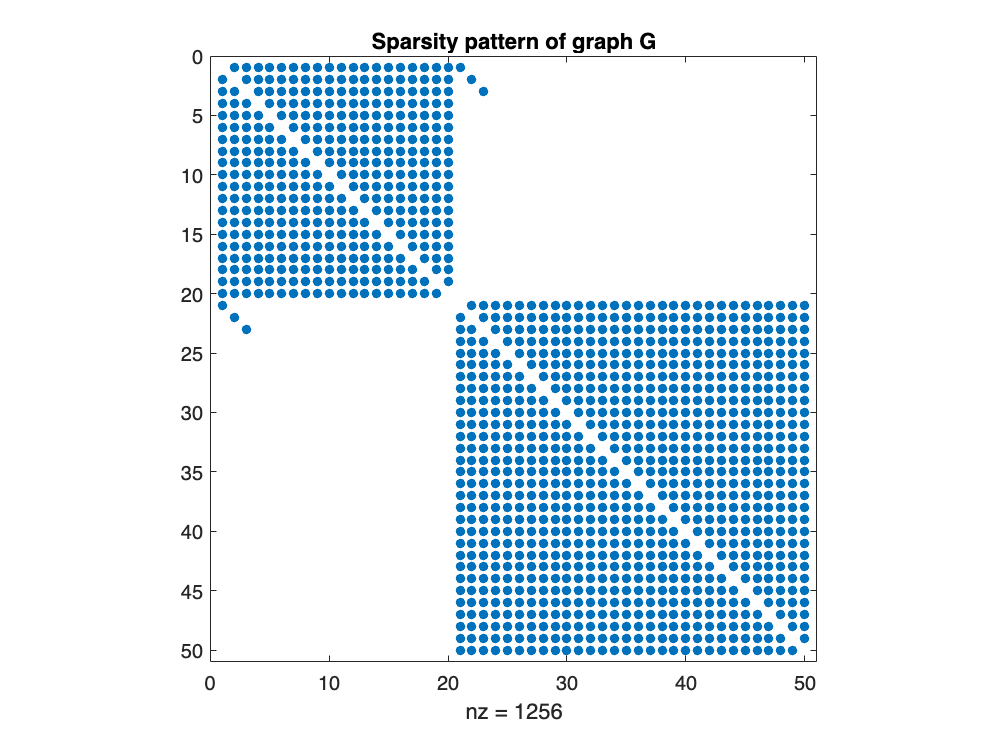

%{
Adjacency matrix
%}
n1=20; 
n2=30;
B1=ones(n1,n1)-diag(ones(1,n1));
B2=ones(n2,n2)-diag(ones(1,n2));
B=[B1, zeros(n1,n2);zeros(n2,n1), B2]; % adjacency matrix B of graph G
for i=1:3
    B(i,n1+i)=1; B(n1+i,i)=1; % bridges
end
%{
Visualization
%}
figure;
spy(B);
title("Sparsity pattern of graph G");

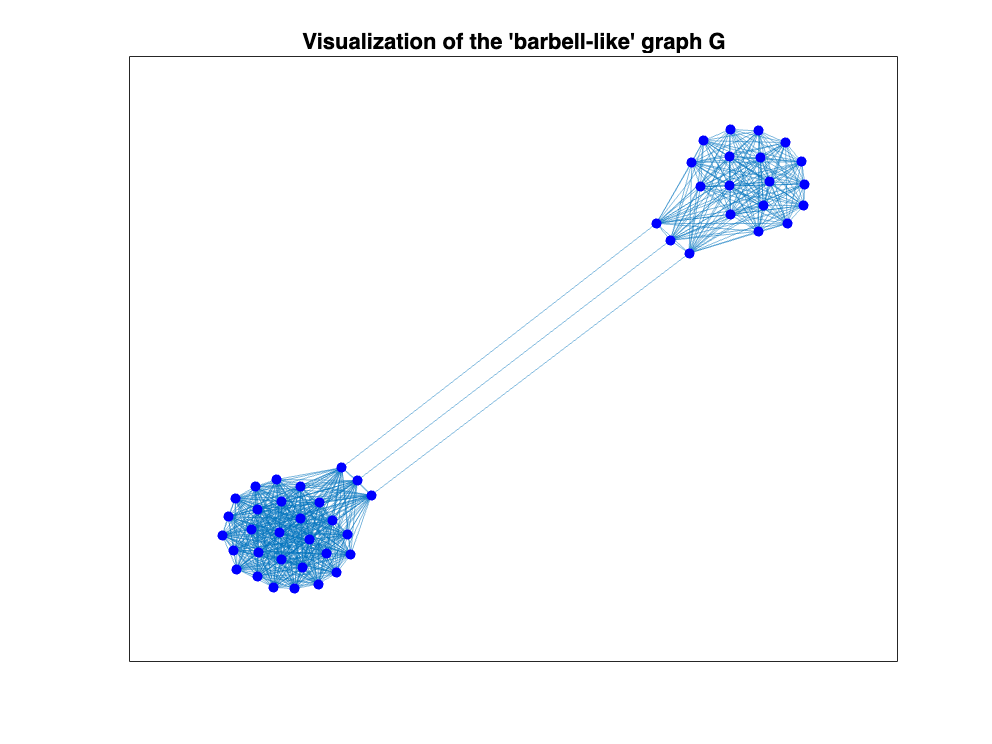

figure;
G = graph(B);
plot(G,'NodeLabel',{},'NodeColor','b');
title("Visualization of the 'barbell-like' graph G");

Use the spectral partitioning method to find a division of the graph $G$ into two subgraphs of size $n_1=20$ and $n_2=30$ such that the number of edges between the subgraphs (the cut size) is minimized. Visualize the obtained partition and find the corresponding cut size. Useful functions for this problem:


$$\texttt{eigs(), find(), highlight(), plot()}$$


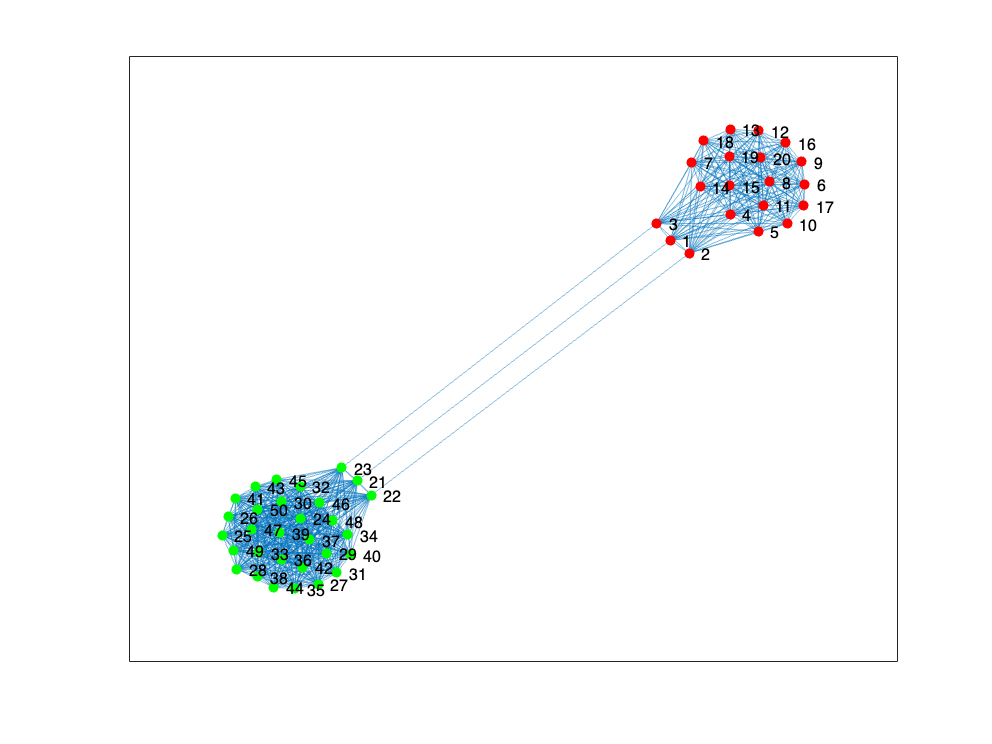

%{
-> Find the graph Laplacian
-> Find the Fiedler vector
-> Determine the 2 candidate partitions
-> Visualize
-> Report the cut size using disp()
%}

% LAPLACIAN & FIEDLER VECTOR
n = 50;
Dv = degree(G);
D = zeros(n);
for i = 1:n
    D(i, i) = Dv(i);
end
L = D - B;
[v, ld] = eigs(L, 2, 'SA');
fiedler = v(:, 2);
% PARTITIONS
b1 = (n1 - n2)/sqrt(n);
b2 = 2*(sqrt(n1*n2/n));
p1 = b1 * ones(n, 1) + b2 * fiedler;
p2 = b1 * ones(n, 1) - b2 * fiedler;

p1s = sort(p1, 'descend');
p2s = sort(p2, 'ascend');
maxvals = p1s(1:n1, 1);
minvals = p2s(1:n1, 1);
maxindices = zeros(0, 1);
minindices = zeros(0, 1);

for j = 1:n1
    if length(maxindices) < n1
        maxsofar = find(p1 == maxvals(j, 1));
        if ~ismember(maxsofar, maxindices)
            maxindices = [maxindices; maxsofar];
        end
    else 
        maxindices = maxindices(1:n1, 1);
    end
    if length(minindices) < n1
        minxsofar = find(p2 == minvals(j, 1));
        if ~ismember(minxsofar, minindices)
            minindices = [minindices; minxsofar];
        end
    else 
        minindices = minindices(1:n1, 1);
    end
end

for i = 1:n
    if ismember(i, maxindices)
        p1(i) = 1;
    else
        p1(i) = -1;
    end
    if ismember(i, minindices)
        p2(i) = 1;
    else
        p2(i) = -1;
    end
end

cutsizep1 = 1/4 * p1' * L * p1;
cutsizep2 = 1/4 * p2' * L * p2;
syms cutsizevar;
if cutsizep1 < cutsizep2
    cutsizevar = p1;
else
    cutsizevar = p2;
end

% VISUALIZATION
gf = plot(G, 'NodeColor', 'g');
locations = find(cutsizevar == 1);
highlight(gf, locations, 'NodeColor', 'r');


% REPORTING CUT SIZE
disp(cutsizep1);

     3



disp(cutsizep2);

     3



%theyre equal

## Problem 1 (10 points) The Power Method (aka Von Mises Iteration)

Let $A$ be an $n\times n$ matrix with eigenvalues $\lambda_1,\cdots,\lambda_n$ such that:


$$|\lambda_1|>|\lambda_2|>\cdots>|\lambda_n|$$


The eigenvalue $\lambda_1$ is called the dominant eigenvalue and the corresponding eigenvector $v_1$ is called the dominant eigenvector. Write a function that takes $A$ as an argument and uses the Power method (Lecture 12) to compute $\lambda_1$ and $v_1$. We can check that $\lambda_1$ is correct by comparing it with the $\texttt{eig()}$ function for a random matrix. An example is provided below:


E = [9,8,7;6,5,4;3,2,1];
[b, d] = eig(E);
[J, VE] = power_method(E);
disp(d(1));

   16.1168



disp(J);

   16.4236



function [lambda, v] = power_method(A)
[n, ~] = size(A); % size of nxn matrix A
v_prev = rand(n, 1); % random starting vector
tol = Inf; % relative error
%{
Implement the algorithm in the while loop
%}
while tol > 1e-15
    intermediate = A * v_prev;
    intermediate = intermediate / norm(intermediate, inf);
    if (norm(intermediate-v_prev, Inf) < tol)
        v_prev = intermediate;
        break;
    end
    v_prev = intermediate;
end
template = A*v_prev;
lambda = template(1)/v_prev(1);
v = v_prev/norm(v_prev);
end